%% ========================================================================
%  Generate Hexagonal Communication Cells over South Korea
%
%  Required Toolbox:
%    - Mapping Toolbox
%
%  Input:
%    - ne_10m_admin_0_countries.shp
%
%  Output:
%    - hexCellTable:
%         CellID
%         CenterLatitude
%         CenterLongitude
%         CenterX_m
%         CenterY_m
%
%  Coordinate system:
%    - Geographic input: WGS84
%    - Grid generation: EPSG:5179
%% ========================================================================

clear;
clc;
close all;

%% ------------------------------------------------------------------------
% User parameters
% -------------------------------------------------------------------------

cellWidthKm = 20;    % Hexagon flat-to-flat width [km]

% true:
%   Keep a cell only when its center lies inside South Korea
%
% false:
%   Keep a cell only when the entire hexagon lies inside South Korea
useCenterPointCriterion = true;

%% ------------------------------------------------------------------------
% 1. Load MATLAB built-in land boundary
% -------------------------------------------------------------------------

landData = shaperead( ...
    "landareas.shp", ...
    "UseGeoCoords", true);

%% ------------------------------------------------------------------------
% 2. Define South Korea geographic bounding region
%
% 경계가 남한과 제주도를 포함하도록 약간 넓게 설정
% -------------------------------------------------------------------------

latitudeMin  = 33.0;
latitudeMax  = 38.7;

longitudeMin = 124.5;
longitudeMax = 130.0;

southKoreaPolygons = polyshape.empty(0, 1);

for i = 1:length(landData)

    latitude  = landData(i).Lat;
    longitude = landData(i).Lon;

    % 현재 land polygon이 남한 bounding box와 겹치는지 확인
    validCoordinate = ...
        ~isnan(latitude) & ...
        ~isnan(longitude);

    if ~any(validCoordinate)
        continue;
    end

    polygonLatitude  = latitude(validCoordinate);
    polygonLongitude = longitude(validCoordinate);

    overlapsSouthKorea = ...
        max(polygonLatitude)  >= latitudeMin  && ...
        min(polygonLatitude)  <= latitudeMax  && ...
        max(polygonLongitude) >= longitudeMin && ...
        min(polygonLongitude) <= longitudeMax;

    if ~overlapsSouthKorea
        continue;
    end

    % 원래 NaN separator를 유지하여 좌표계 변환
    latitude  = latitude(:);
    longitude = longitude(:);

    koreaCRS = projcrs(5179);

    [polygonX, polygonY] = projfwd( ...
        koreaCRS, ...
        latitude, ...
        longitude);

    currentPolygon = polyshape( ...
        polygonX, ...
        polygonY, ...
        "Simplify", true);

    if currentPolygon.NumRegions > 0
        southKoreaPolygons(end + 1, 1) = currentPolygon;
    end
end

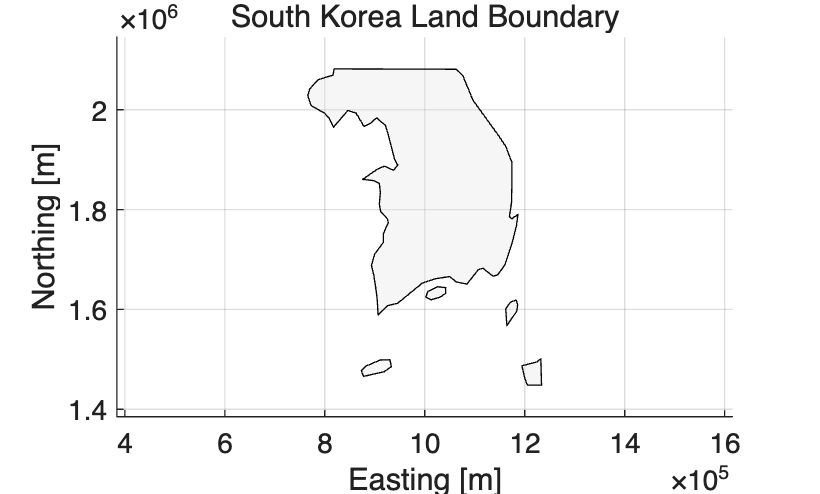


%% ------------------------------------------------------------------------
% 3. Combine polygons and crop to South Korea bounding box
% -------------------------------------------------------------------------

if isempty(southKoreaPolygons)
    error("남한 범위에 해당하는 육지 polygon을 찾지 못했습니다.");
end

southKoreaPolygon = southKoreaPolygons(1);

for i = 2:length(southKoreaPolygons)
    southKoreaPolygon = union( ...
        southKoreaPolygon, ...
        southKoreaPolygons(i));
end

% 남한 bounding box를 EPSG:5179로 변환
boxLatitude = [ ...
    latitudeMin;
    latitudeMin;
    latitudeMax;
    latitudeMax];

boxLongitude = [ ...
    longitudeMin;
    longitudeMax;
    longitudeMax;
    longitudeMin];

[boxX, boxY] = projfwd( ...
    koreaCRS, ...
    boxLatitude, ...
    boxLongitude);

southKoreaBoundingPolygon = polyshape( ...
    boxX, ...
    boxY);

southKoreaPolygon = intersect( ...
    southKoreaPolygon, ...
    southKoreaBoundingPolygon);

if southKoreaPolygon.NumRegions == 0
    error("남한 육지 polygon 생성에 실패했습니다.");
end

%% Plot boundary check
figure;

plot( ...
    southKoreaPolygon, ...
    "FaceColor", [0.9 0.9 0.9], ...
    "EdgeColor", "k");

axis equal;
grid on;

title("South Korea Land Boundary");
xlabel("Easting [m]");
ylabel("Northing [m]");


%% ------------------------------------------------------------------------
% 4. Define regular hexagon geometry
%
% Pointy-top hexagon:
%
%   flat-to-flat width = sqrt(3) * R
%
% where R is center-to-vertex distance.
% -------------------------------------------------------------------------

cellWidthM = cellWidthKm * 1000;

hexRadius = cellWidthM / sqrt(3);

% Pointy-top hexagonal lattice spacing
horizontalSpacing = sqrt(3) * hexRadius;
verticalSpacing   = 1.5 * hexRadius;

%% ------------------------------------------------------------------------
% 5. Generate candidate hexagon center points
% -------------------------------------------------------------------------

[xLimits, yLimits] = boundingbox(southKoreaPolygon);

xMin = xLimits(1) - 2 * horizontalSpacing;
xMax = xLimits(2) + 2 * horizontalSpacing;

yMin = yLimits(1) - 2 * verticalSpacing;
yMax = yLimits(2) + 2 * verticalSpacing;

centerXCandidate = [];
centerYCandidate = [];

rowIndex = 0;

for centerY = yMin:verticalSpacing:yMax

    rowIndex = rowIndex + 1;

    % 인접한 행을 반 셀만큼 이동
    if mod(rowIndex, 2) == 0
        xOffset = horizontalSpacing / 2;
    else
        xOffset = 0;
    end

    xRow = ...
        (xMin + xOffset):horizontalSpacing:(xMax + xOffset);

    yRow = centerY * ones(size(xRow));

    centerXCandidate = [centerXCandidate; xRow(:)];
    centerYCandidate = [centerYCandidate; yRow(:)];

end

%% ------------------------------------------------------------------------
% 6. Select cells associated with South Korea
% -------------------------------------------------------------------------

if useCenterPointCriterion

    % 중심점이 남한 내부에 있는 셀 선택
    selectedIndex = isinterior( ...
        southKoreaPolygon, ...
        centerXCandidate, ...
        centerYCandidate);

else

    % 전체 육각형이 남한 polygon 내부에 있는 경우만 선택
    selectedIndex = false(size(centerXCandidate));

    hexAngleDeg = 90 + (0:5) * 60;
    hexAngleRad = deg2rad(hexAngleDeg);

    for i = 1:length(centerXCandidate)

        vertexX = centerXCandidate(i) + ...
            hexRadius * cos(hexAngleRad);

        vertexY = centerYCandidate(i) + ...
            hexRadius * sin(hexAngleRad);

        vertexInside = isinterior( ...
            southKoreaPolygon, ...
            vertexX, ...
            vertexY);

        selectedIndex(i) = all(vertexInside);

    end

end

centerX = centerXCandidate(selectedIndex);
centerY = centerYCandidate(selectedIndex);

%% ------------------------------------------------------------------------
% 7. Convert cell centers back to latitude and longitude
% -------------------------------------------------------------------------

[centerLatitude, centerLongitude] = ...
    projinv(koreaCRS, centerX, centerY);

%% ------------------------------------------------------------------------
% 8. Create output table
% -------------------------------------------------------------------------

numberOfCells = length(centerX);

cellID = compose("Cell_%03d", (1:numberOfCells)');

hexCellTable = table( ...
    cellID, ...
    centerLatitude, ...
    centerLongitude, ...
    centerX, ...
    centerY, ...
    'VariableNames', { ...
        'CellID', ...
        'CenterLatitude', ...
        'CenterLongitude', ...
        'CenterX_m', ...
        'CenterY_m'});

disp(hexCellTable);

      CellID      CenterLatitude    CenterLongitude    CenterX_m     CenterY_m 
    __________    ______________    _______________    __________    __________

    "Cell_001"         33.16            129.82          1.216e+06    1.4656e+06
    "Cell_002"        33.331            126.28         8.8602e+05    1.4829e+06
    "Cell_003"        33.333            126.49         9.0602e+05    1.4829e+06
    "Cell_004"        33.335            126.71         9.2602e+05    1.4829e+06
    "Cell_005"        33.318            129.71          1.206e+06    1.4829e+06
    "Cell_006"        33.314            129.93          1.226e+06    1.4829e+06
    "Cell_007"        34.262             129.3          1.166e+06    1.5868e+06
    "Cell_008"        34.428            126.59         9.1602e+05    1.6041e+06
    "Cell_009"        34.416            129.42          1.176e+06    1.6041e+06
    "Cell_010"        34.583            126.48         9.0602e+05    1.6215e+06
    "Cell_011"        34.585           


fprintf("\nCell width       : %.1f km\n", cellWidthKm);


Cell width       : 20.0 km


fprintf("Number of cells  : %d\n", numberOfCells);

Number of cells  : 342


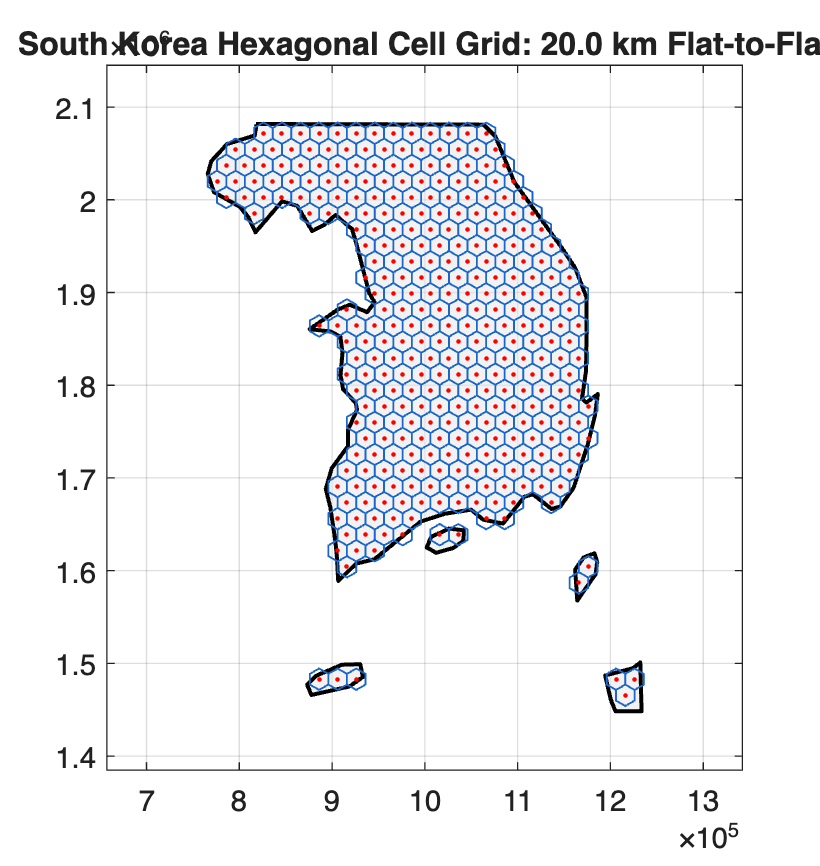


%% ------------------------------------------------------------------------
% 9. Generate selected hexagon polygons
% -------------------------------------------------------------------------

hexAngleDeg = 90 + (0:6) * 60;
hexAngleRad = deg2rad(hexAngleDeg);

hexPolygons = polyshape.empty(numberOfCells, 0);

for i = 1:numberOfCells

    vertexX = centerX(i) + ...
        hexRadius * cos(hexAngleRad);

    vertexY = centerY(i) + ...
        hexRadius * sin(hexAngleRad);

    hexPolygons(i) = polyshape(vertexX, vertexY);

end

%% ------------------------------------------------------------------------
% 10. Plot in projected coordinate system
% -------------------------------------------------------------------------

figure( ...
    'Name', 'South Korea Hexagonal Cell Grid', ...
    'Position', [100 100 900 950]);

hold on;

plot( ...
    southKoreaPolygon, ...
    'FaceColor', [0.90 0.90 0.90], ...
    'FaceAlpha', 0.5, ...
    'EdgeColor', 'k', ...
    'LineWidth', 1.5);

for i = 1:numberOfCells
    plot( ...
        hexPolygons(i), ...
        'FaceColor', 'none', ...
        'EdgeColor', [0.1 0.4 0.8], ...
        'LineWidth', 0.7);
end

scatter( ...
    centerX, ...
    centerY, ...
    3, ...
    'filled', ...
    'r');

axis equal;
grid on;
box on;

% xlabel('Easting [m]');
% ylabel('Northing [m]');

title(sprintf( ...
    'South Korea Hexagonal Cell Grid: %.1f km Flat-to-Flat', ...
    cellWidthKm),'FontSize',12,'FontWeight','bold');



writetable( ...
    hexCellTable, ...
    sprintf('South_Korea_Hex_Cell_Centers_%gkm.csv', cellWidthKm));